%cleaning workspace
clear;

% Load dataset
load Dataset_task2.mat;
%Dataset presenta dati mancanti o errati e colonna 19 duplicata di 18
short_matrix_no_id(:,19) = [];
short_matrix_no_id = fillmissing(short_matrix_no_id,"knn");
short_matrix_no_id(:,[2:4]) = normalize(short_matrix_no_id(:,[2:4]), 'range', [0, 1]);
short_matrix_no_id(:,[5,9:15,18]) = zscore(short_matrix_no_id(:,[5,9:15,18]));

% Replace the original IDs in the dataset with the new IDs

X = short_matrix_no_id;
Y = short_matrix_no_id(:,15);

% Split data into training and testing sets
train_ratio = 0.7;
train_size = round(train_ratio*size(X,1));
train_idx = randperm(size(X,1),train_size);
test_idx = setdiff(1:size(X,1),train_idx);
X_train = X(train_idx,:);
Y_train = Y(train_idx,:);
X_test = X(test_idx,:);
Y_test = Y(test_idx,:);


% Define neural network
input_size = size(X_train,2);
output_size = 1;
hidden_size = 12;
net = fitnet(hidden_size);
net.trainFcn = 'trainbr'; % Bayesian regulation algorithm
net.divideFcn = 'dividerand'; % Random division of data into training and validation sets
net.divideParam.trainRatio = 0.2; % Training set proportion
net.divideParam.valRatio = 1 - net.divideParam.trainRatio; % Validation set proportion
net.divideParam.testRatio = 0; % No testing set
net.trainParam.max_fail = 20; % Maximum validation failures
net.trainParam.epochs = 5; % Maximum number of epochs
net.trainParam.goal = 1e-5; % Training goal
net.performFcn = 'mse'; % Mean squared error performance function

% Train neural network
avg_accuracy = 0;
avg_MSE = 0

avg_MSE = 0

avg_COV = 0

avg_COV = 0

n_cycle=50

n_cycle = 50

covariance_matrix =     0.7847    0.8860
    0.8860    1.0005


avg_COV = 4.7239e+03

covariance_matrix =     0.9977    0.9991
    0.9991    1.0005


avg_COV = 1.0555e+04

covariance_matrix =     1.0001    1.0003
    1.0003    1.0005


avg_COV = 1.6400e+04

covariance_matrix =     1.0005    1.0005
    1.0005    1.0005


avg_COV = 2.2247e+04

covariance_matrix =     1.0003    1.0004
    1.0004    1.0005


avg_COV = 2.8093e+04

covariance_matrix =     1.0004    1.0004
    1.0004    1.0005


avg_COV = 3.3939e+04

covariance_matrix =     1.0004    1.0004
    1.0004    1.0005


avg_COV = 3.9786e+04

covariance_matrix =     1.0004    1.0004
    1.0004    1.0005


avg_COV = 4.5632e+04

covariance_matrix =     1.0006    1.0005
    1.0005    1.0005


avg_COV = 5.1480e+04

covariance_matrix =     1.0006    1.0005
    1.0005    1.0005


avg_COV = 5.7328e+04

covariance_matrix =     1.0006    1.0005
    1.0005    1.0005


avg_COV = 6.3176e+04

covariance_matrix =     1.0006    1.0005
    1.0005    1.0005


avg_COV = 6.9024e+04

covariance_matrix =     1.0009    1.0007
    1.0007    1.0005


avg_COV = 7.4873e+04

covariance_matrix =     1.0009    1.0007
    1.0007    1.0005


avg_COV = 8.0723e+04

covariance_matrix =     1.0009    1.0007
    1.0007    1.0005


avg_COV = 8.6572e+04

covariance_matrix =     1.0009    1.0007
    1.0007    1.0005


avg_COV = 9.2422e+04

covariance_matrix =     1.0009    1.0007
    1.0007    1.0005


avg_COV = 9.8271e+04

covariance_matrix =     1.0009    1.0007
    1.0007    1.0005


avg_COV = 1.0412e+05

covariance_matrix =     1.0009    1.0007
    1.0007    1.0005


avg_COV = 1.0997e+05

covariance_matrix =     1.0009    1.0007
    1.0007    1.0005


avg_COV = 1.1582e+05

covariance_matrix =     1.0009    1.0007
    1.0007    1.0005


avg_COV = 1.2167e+05

covariance_matrix =     1.0009    1.0007
    1.0007    1.0005


avg_COV = 1.2752e+05

covariance_matrix =     1.0009    1.0007
    1.0007    1.0005


avg_COV = 1.3337e+05

covariance_matrix =     1.0009    1.0007
    1.0007    1.0005


avg_COV = 1.3922e+05

covariance_matrix =     1.0009    1.0007
    1.0007    1.0005


avg_COV = 1.4507e+05

covariance_matrix =     1.0009    1.0007
    1.0007    1.0005


avg_COV = 1.5092e+05

covariance_matrix =     1.0009    1.0007
    1.0007    1.0005


avg_COV = 1.5677e+05

covariance_matrix =     1.0009    1.0007
    1.0007    1.0005


avg_COV = 1.6262e+05

covariance_matrix =     1.0009    1.0007
    1.0007    1.0005


avg_COV = 1.6846e+05

covariance_matrix =     1.0009    1.0007
    1.0007    1.0005


avg_COV = 1.7431e+05

covariance_matrix =     1.0009    1.0007
    1.0007    1.0005


avg_COV = 1.8016e+05

covariance_matrix =     1.0009    1.0007
    1.0007    1.0005


avg_COV = 1.8601e+05

covariance_matrix =     1.0009    1.0007
    1.0007    1.0005


avg_COV = 1.9186e+05

covariance_matrix =     1.0009    1.0007
    1.0007    1.0005


avg_COV = 1.9771e+05

covariance_matrix =     1.0009    1.0007
    1.0007    1.0005


avg_COV = 2.0356e+05

covariance_matrix =     1.0009    1.0007
    1.0007    1.0005


avg_COV = 2.0941e+05

covariance_matrix =     1.0009    1.0007
    1.0007    1.0005


avg_COV = 2.1526e+05

covariance_matrix =     1.0009    1.0007
    1.0007    1.0005


avg_COV = 2.2111e+05

covariance_matrix =     1.0009    1.0007
    1.0007    1.0005


avg_COV = 2.2696e+05

covariance_matrix =     1.0009    1.0007
    1.0007    1.0005


avg_COV = 2.3281e+05

covariance_matrix =     1.0009    1.0007
    1.0007    1.0005


avg_COV = 2.3866e+05

covariance_matrix =     1.0009    1.0007
    1.0007    1.0005


avg_COV = 2.4451e+05

covariance_matrix =     1.0009    1.0007
    1.0007    1.0005


avg_COV = 2.5036e+05

covariance_matrix =     1.0009    1.0007
    1.0007    1.0005


avg_COV = 2.5621e+05

covariance_matrix =     1.0009    1.0007
    1.0007    1.0005


avg_COV = 2.6206e+05

covariance_matrix =     1.0009    1.0007
    1.0007    1.0005


avg_COV = 2.6791e+05

covariance_matrix =     1.0009    1.0007
    1.0007    1.0005


avg_COV = 2.7375e+05

covariance_matrix =     1.0009    1.0007
    1.0007    1.0005


avg_COV = 2.7960e+05

covariance_matrix =     1.0009    1.0007
    1.0007    1.0005


avg_COV = 2.8545e+05

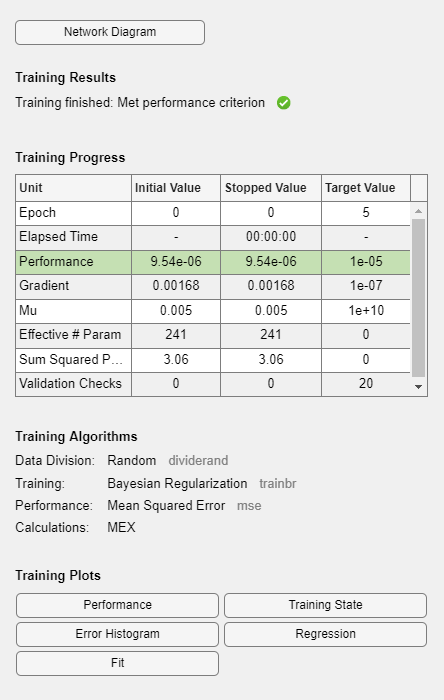

covariance_matrix =     1.0009    1.0007
    1.0007    1.0005


avg_COV = 2.9130e+05

for i = 1:n_cycle
    [net,tr] = train(net,X_train',Y_train');
    
    % Test neural network
    Y_pred = net(X_test');
    
    % Display the covariance matrix and error
    covariance_matrix = cov(Y_pred,Y_test);
    covariance_matrix
    % Calculate the covariance error
    cov_error = sum(sum((cov(Y_pred) - Y_test).^2));
    acc = mean(abs(Y_pred-Y_test')<0.05);

    avg_accuracy = avg_accuracy + acc;
    avg_MSE = avg_MSE + mse(net,Y_pred,Y_test');
    avg_COV = avg_COV + cov_error
end

avg_accuracy = avg_accuracy/n_cycle;
avg_COV = avg_accuracy/n_cycle;
avg_MSE = avg_MSE/n_cycle;
'AVG ACCURACY: '+ avg_accuracy

ans = 1×14
   65.9870   86.9870   71.9870   32.9870   65.9870   67.9870   67.9870   85.9870   82.9870   65.9870   67.9870   89.9870   58.9870   32.9870


'AVG MSE: '+ avg_MSE

ans = 1×9
   65.0003   86.0003   71.0003   32.0003   77.0003   83.0003   69.0003   58.0003   32.0003


'AVG COV: '+ avg_COV

ans = 1×9
   65.0197   86.0197   71.0197   32.0197   67.0197   79.0197   86.0197   58.0197   32.0197


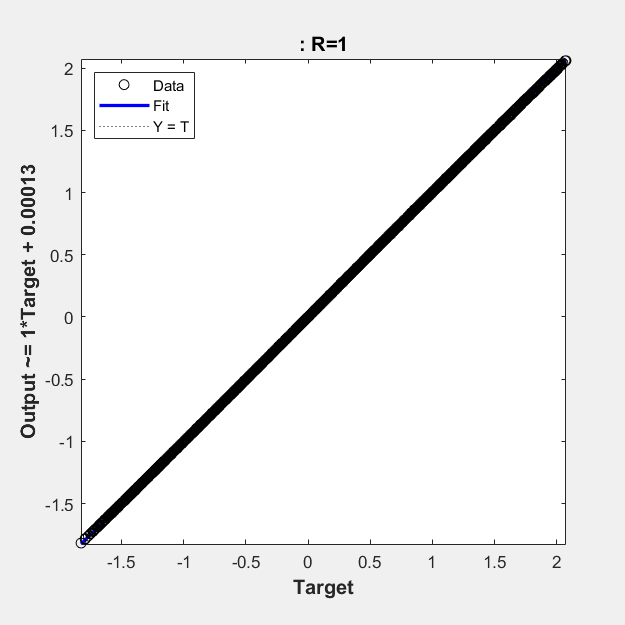

plotregression(Y_test',Y_pred);